Create image with csv file (execute this when first time)

% % create a folder "train" with another 10 subfolders 0 to 9
% for i = 0:9
%     mkdir("train\" + i);
% end
%  
% % open the training csv file
% trainData = readtable("mnist_train.csv");
%  
% % create two matrices where TrainX contains the training data's pixel values
% %   and TrainY contains the training data's labels
% TrainX = table2array(trainData(:,2:end));
% TrainX = double(TrainX ./ 255);
% TrainY = table2array(trainData(:,1));
%  
% % now we reshape each row in image_train_Kaggle.csv to jpg image,
% %   then save each image into the subfolder inside "train" based
% %   on the image corresponding label
% for i = 1:length(TrainY)
%     name = "train\" + TrainY(i) + "\train" + i + "_1.jpg";
%     img = reshape(TrainX(i,:), 28, 28)';
%     imwrite(img, name);
% end
%  
% % delete the varables we do not need anymore
% clear

Loading Image we created and split 1500 0~9 to training data and 500 0~9 to testing data

imds=imageDatastore("train\","IncludeSubfolders",true,"LabelSource","foldernames");
[trainimds,validimds]=splitEachLabel(imds,1500,500,"randomized");
clear imds;

Network architecture

layers = [
    imageInputLayer([28 28 1],"Name","imageinput")
    convolution2dLayer([3 3],12,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])
    convolution2dLayer([3 3],24,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],48,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution2dLayer([1 1],64,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

Training options

options = trainingOptions('sgdm', ...
    'MiniBatchSize',25, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validimds, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',100, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'OutputNetwork','best-validation-loss');

Start training

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |        8.00% |       21.16% |       2.7225 |       3.4923 |          0.0100 |
|       1 |          10 |       00:00:17 |       48.00% |       67.50% |       2.5794 |       1.9790 |          0.0100 |
|       1 |          20 |       00:00:20 |       80.00% |       73.98% |       1.0970 |       1.6715 |          0.0100 |
|       1 |          30 |       00:00:22 |       80.00% |       76.08% |       1.3303 |   

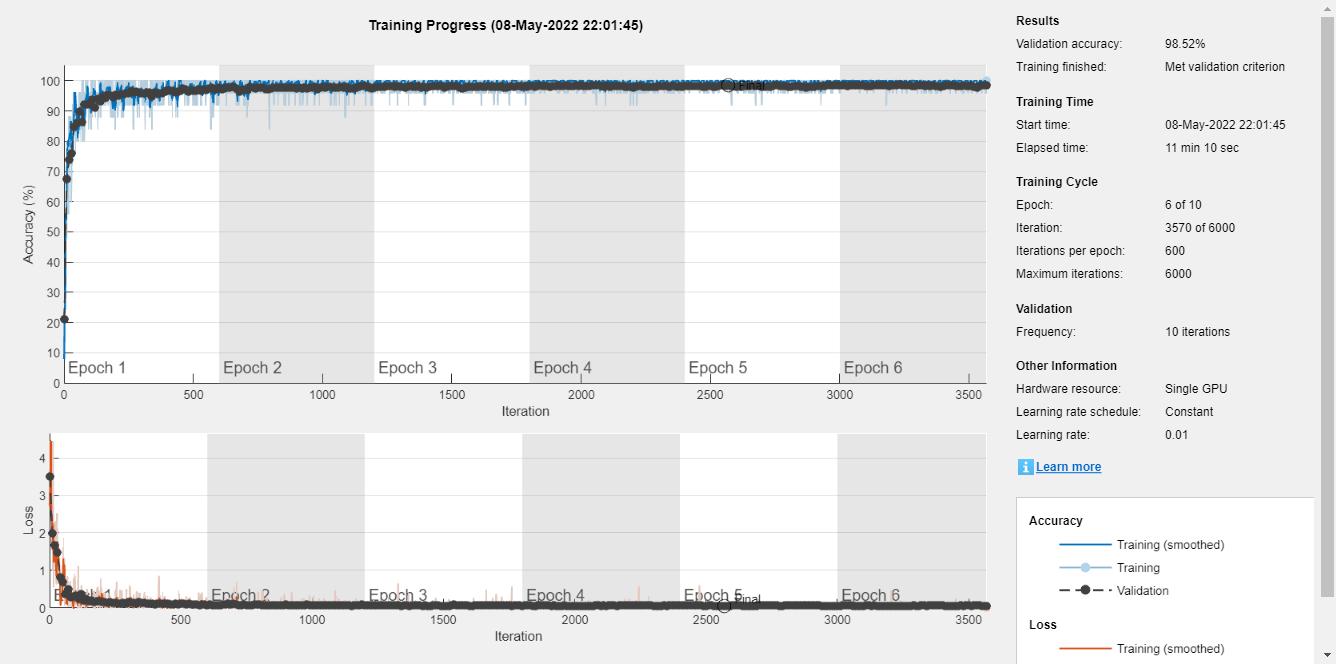

mymnistnet =   SeriesNetwork with properties:

         Layers: [17×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


mymnistnet = trainNetwork(trainimds, layers, options)

Get features and check the image we extract

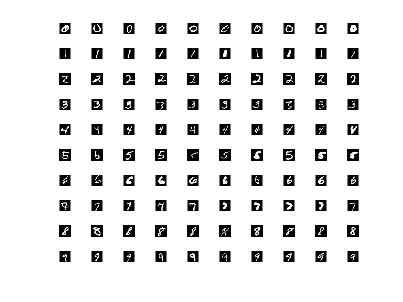

featureTrain = activations(mymnistnet,trainimds,"relu_4","OutputAs","rows");
featureTrain = featureTrain-min(featureTrain(:));
featureTrain = featureTrain/max(featureTrain(:));
figure(1);
for i=1:10
    for j=1:10
        subplot(10,10,(i-1)*10+j);
        kk=(i-1)*1500+j;
        tmp=readimage(trainimds,kk);
        imshow(tmp);
    end
end

Plot features

figure(2);
for i=1:10
    for j=1:10
        subplot(10,10,(i-1)*10+j);
        kk=(i-1)*1500+j;
        tmp=featureTrain(kk,:);
        imshow(reshape(tmp,98,128));%1x12544 to 98x128
    end
end
colormap("jet");

Plot confusion chart

testpreds = classify(mymnistnet,validimds);
accuracy = nnz(testpreds == validimds.Labels)/numel(testpreds)

accuracy = 0.9852

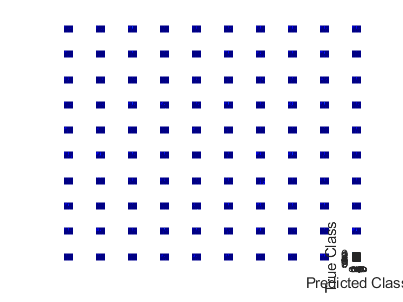

confusionchart(validimds.Labels,testpreds);

Get 120 ramdom data from validation data

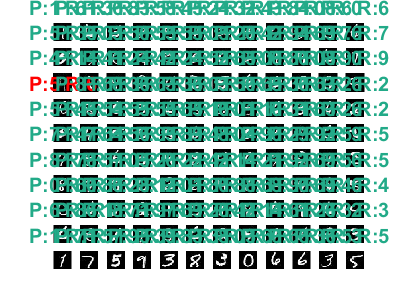

figure(3);
for i=1:10
    for j=1:12
        subplot(10,12,(i-1)*12+j);
        kk=floor(rand*5000);
        tmp=readimage(validimds,kk);
        imshow(tmp);
        real=string(validimds.Labels(kk));
        pred=string(testpreds(kk));
        if pred==real
            title("P:"+pred+" R:"+real,Color="#22AA88",FontSize=12);
        else
            title("P:"+pred+" R:"+real,Color="red",FontSize=12);
        end
    end
end